# NWB Tutorial - Reading NWB Data from DANDI Using MatNWB

## Installing MatNWB

Use the code below within the brackets to install MatNWB from source (remove the brackets, then run the cell). 

MatNWB works by automatically creating API classes based on the schema. Use `generateCore()` to generate these classes.

%{
!git clone https://github.com/NeurodataWithoutBorders/matnwb.git

categories
dynamictable
-> DynamicTable
data
indices
indptr
shape
data
colnames
description
id
vectordata
data
description
table
data
container
-> Container
data
data
description
data
target
data
elements
entities
keys
object_keys
objects
resources
data
data_unit
feature_units
features
data
intervalseries
-> IntervalSeries
timeseries
-> TimeSeries
timeseries
-> TimeSeries
clustering_interface
waveform_filtering
waveform_mean
waveform_sd
description
num
peak_over_rms
times
spatialseries
-> SpatialSeries
corrected
-> ImageSeries
original
xy_translation
-> TimeSeries
bias_current
bridge_balance
capacitance_compensation
data
data
bands
-> DynamicTable
data
data_unit
metric
source_channels
source_timeseries
description
manufacturer
roiresponseseries
-> RoiResponseSeries
channel_conversion
data
electrodes
filtering
description
device
location
position
detection_method
source_electricalseries
source_idx
times
spikeeventseries
-> SpikeEventSeries
repetitions
repetitions_index
spatialseries
-> 

cd matnwb
addpath(genpath(pwd));
generateCore();
%}

## Read NWB data by streaming it from DANDI

Go to [dandiset 223 on the DANDI Archive](https://dandiarchive.org/dandiset/000223), then click 

Navigate to the first subject folder "sub-2282".

In the first row that lists an .nwb file, click  

Find the second entry of "contentUrl":

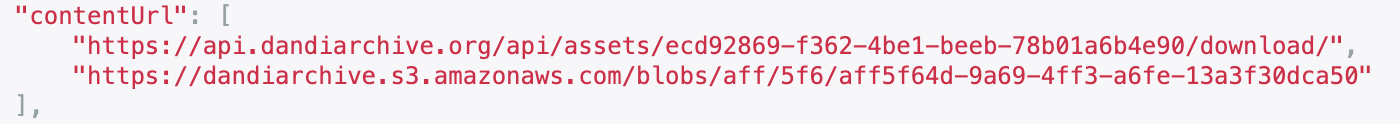

In your MATLAB session, take the end of that URL and stick it onto `s3 = 's3_url://dandiarchive/blobs/`. In this example, you would have 

`s3_url = 's3://dandiarchive/blobs/aff/5f6/aff5f64d-9a69-4ff3-a6fe-13a3f30dca50'`

Then call `nwbRead` on that URL to stream basic metadata about the NWB file to your computer.

s3_url = 's3://dandiarchive/blobs/aff/5f6/aff5f64d-9a69-4ff3-a6fe-13a3f30dca50';
nwb = nwbRead(s3_url);

data
data_continuity
data_conversion
data_resolution
data_unit
feature_units
features
data
data_continuity
data_conversion
intervalseries
-> IntervalSeries
timeseries
-> TimeSeries
timeseries
-> TimeSeries
clustering_interface
waveform_filtering
waveform_mean
waveform_sd
description
num
peak_over_rms
times
spatialseries
-> SpatialSeries
corrected
-> ImageSeries
original
xy_translation
-> TimeSeries
bias_current
bridge_balance
capacitance_compensation
data
data_continuity
data_conversion
data_resolution
data
data_continuity
data_conversion
data_resolution
bands
-> DynamicTable
data
data_continuity
data_conversion
data_resolution
data_unit
metric
source_channels
source_timeseries
description
manufacturer
roiresponseseries
-> RoiResponseSeries
channel_conversion
data
data_continuity
data_conversion
data_resolution
electrodes
filtering
description
device
location
position
detection_method
source_electricalseries
source_idx
times
spikeeventseries
-> SpikeEventSeries
repetitions
repetitions_

Explore the raw data in the NWB file by looking in the `nwb.acquisition` group:

nwb.acquisition

ans =   2×1 Set array with properties:

    ElectricalSeries_raw: [types.core.ElectricalSeries]
         TwoPhotonSeries: [types.core.TwoPhotonSeries]


There are two raw data objects - an ElectricalSeries and a TwoPhotonSeries. In this example, let's use the TwoPhotonSeries object.

## Lazy loading of datasets

Data arrays are read passively from the NWB file. Calling the `data` attribute on a `TimeSeries`, such as our example `TwoPhotonSeries`, does not read the data values, but presents a DataPipe object that can be indexed to read the data. This allows you to conveniently work with datasets that are too large to fit in RAM all at once. You can call the `load` function without inputs to read the entire data array into memory, or you can pass two inputs to access a slice or region of the data array - the first input describes the starting points in each dimension, and the second describes the ending points. 

Let's load the first image. Compared to PyNWB, the dimensions mapping is completely flipped. So time is always the last axis.

The following code will load the first image from the TwoPhotonSeries object. This can take some time to run because we are streaming the data in chunks over the internet.

% all_images = nwb.acquisition.get('TwoPhotonSeries').data.load;
first_image = nwb.acquisition.get('TwoPhotonSeries').data.load([1,1,1],[512,512,1])'

first_image = 512×512 uint16 matrix
    716    717    843    863   1138    960   1224   1564   1801   1093   1353    902    669    643    578    833    720    640    589    535    611    642    571    606    711    679    663    607    704    691    680    590    647    781    653    766    770    717    565    641    582    740    818    960    778    638    590    688    615    661
    858    918    893    898    857    870    883   1268   2281   1758   1797    963   1197    949    762    695    641    719    592    554    597    686    701    619    782    639    672    658    532    610    527    729    648    647    622    709    695    703    621    728    661    670    749    751   1015    682    580    575    737    690
   1075   1491    972    575    586    892    628    772   1261   1866   1765   1600    834    805    577    582    564    603    597    765    764    644    676    571    608    593    627    642    577    700    671    530    614    573    701    717    890   

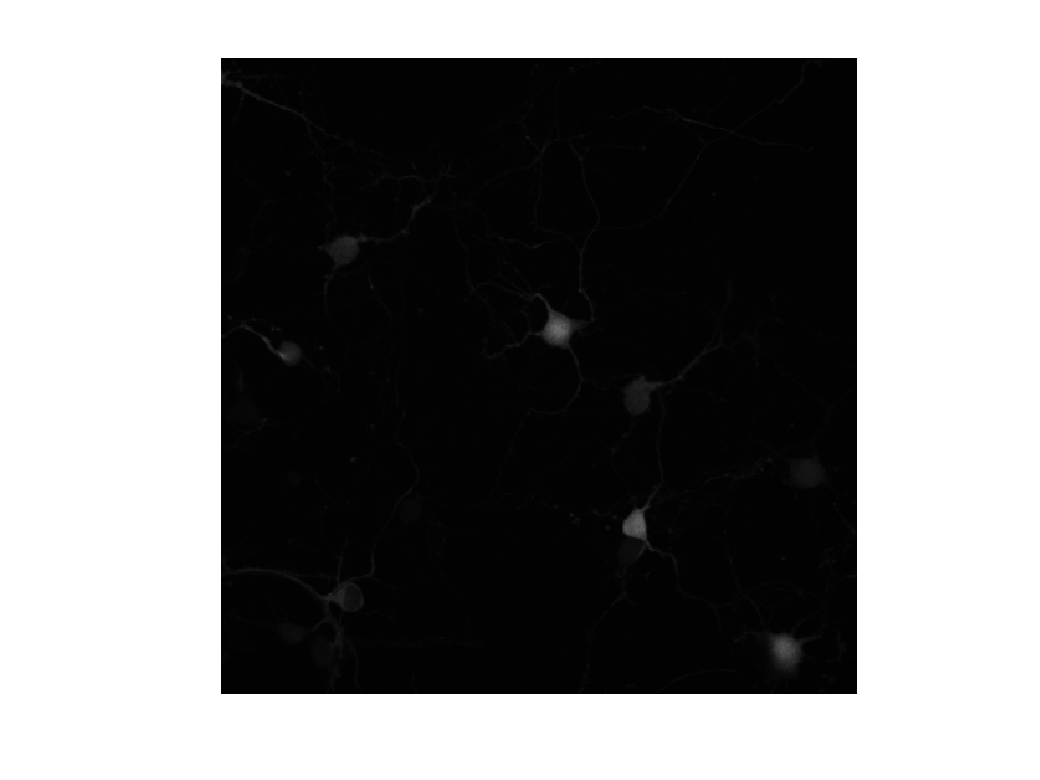

imshow(first_image)

Similarly, you can access the `ElectricalSeries` in the `acquisition` group of the NWB file and select a particular region of it to read. For example, the following code reads the first 1000 samples of the first channel of the raw electrical recording by streaming it from DANDI. We can see from the print out of `nwb.acquisition` above that the `ElectricalSeries` object is named `'ElectricalSeries_raw'`, so we can use that key to index the `nwb.acquisition` object.

first_channel = nwb.acquisition.get('ElectricalSeries_raw').data.load([1,1],[1,1000])'

first_channel = 1000×1 uint16 column vector
   509
   508
   509
   512
   513
   513
   511
   510
   512
   510


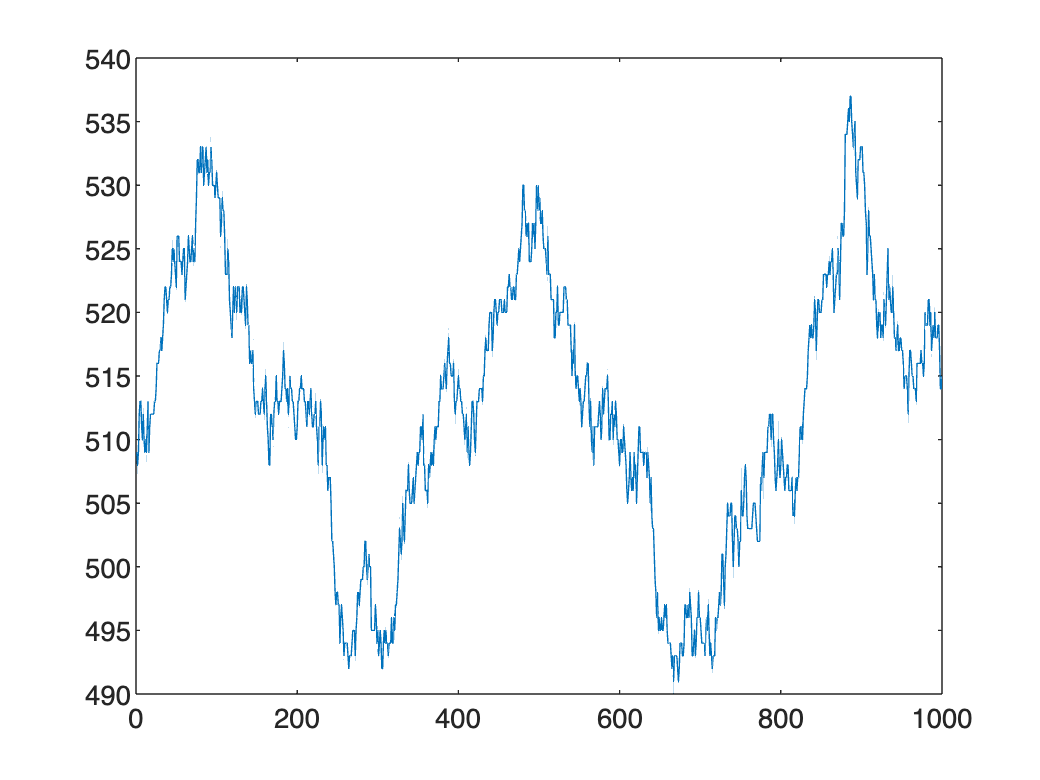

plot(first_channel)

## Access single unit data in NWB

This dandiset happens to have both optical physiology data and extracellular ephys data. Data and metadata about sorted single units are stored in `NWBFile.units`. `NWBFile.units` is a `Units` object that stores metadata about each single unit in a tabular form, where each row represents a unit and has spike times and additional metadata. Printing the `Units` object shows the column names and basic metadata associated with each unit.

When working with table object like the units table, the ROIs table, or the electodes table, you can use the `getRow` method of the table to load spike times of a specific unit. To get the values, unpack them from the returned table.

nwb.units

ans =   Units with properties:

          electrode_group: []
               electrodes: []
         electrodes_index: []
            obs_intervals: []
      obs_intervals_index: []
              spike_times: [1×1 types.hdmf_common.VectorData]
        spike_times_index: [1×1 types.hdmf_common.VectorIndex]
            waveform_mean: []
              waveform_sd: []
                waveforms: []
          waveforms_index: []
    waveforms_index_index: []
                 colnames: {'spike_times'}
              description: 'Autogenerated by NWBFile'
                       id: [1×1 types.hdmf_common.ElementIdentifiers]
               vectordata: [0×1 types.untyped.Set]


nwb.units.getRow(1).spike_times{1}

ans =     1.4221
    1.5522
    1.5681
    1.6005
    2.2936
    3.0260
    3.1581
    3.1663
    3.1799
    3.2138


## Exploring the NWB file

You can explore the NWB file by printing the `NWBFile` object and accessing its attributes, but it may be useful to explore the data in a less programmatic, more visual way. You can use NWBWidgets, a package containing interactive widgets for visualizing NWB data, or you can use the HDFView tool, which can open any generic HDF5 file, which an NWB file is.

## Conclusion

This is an example of how to get started with understanding and analyzing public NWB datasets. For more datasets, or to publish your own NWB data for free, check out the DANDI Archive.

# Learn more!

### See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.

## MATLAB tutorials

- [Optical physiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

## Python tutorials

See our tutorials for more details about your data type:

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/icephys.html#sphx-glr-tutorials-domain-icephys-py)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/general/iterative_write.html#sphx-glr-tutorials-general-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/general/advanced_hdf5_io.html#sphx-glr-tutorials-general-advanced-hdf5-io-py)